# Result Analyze

close all;clear;clc;
addpath models/
load data/rat_010_07_04_spike_train_selected_with_delay_8.mat
load results/GLM_explore_H_w_8.mat
load results/GLM_sec_explore_H_w_8.mat
load results/ANN_explore_Nz_new.mat
load results/ANN_explore_H_w_8_0407.mat
load results/ANN_explore_xi.mat

% ANN xi
% best, avrage, middle, number of less than 0.8?
DBRtable = zeros(7,7,20);
LTable = zeros(7,7,20);
for xi1No=1:7
  for xi2No=1:7
    for index=1:20
      DBRtable(xi1No, xi2No, index) = ANN_explore_xi(xi1No, xi2No, index).DBR;
      LTable(xi1No, xi2No, index) = ANN_explore_xi(xi1No, xi2No, index).L;
    end
  end
end
xi_bestDBR = zeros(7,7);
xi_bestL = zeros(7,7);
xi_avrDBR = zeros(7,7);
xi_avrL = zeros(7,7);
xi_medDBR = zeros(7,7);
xi_medL = zeros(7,7);
xi_fairDBR = zeros(7,7);
xi_fairL = zeros(7,7);
for i=1:7
  for j=1:7
    xi_bestDBR(i, j) = min(DBRtable(i, j,:));
    xi_bestL(i,j) = max(LTable(i,j,:));
    xi_avrDBR(i, j) = mean(DBRtable(i, j,:));
    xi_avrL(i,j) = mean(LTable(i,j,:));
    xi_medDBR(i, j) = median(DBRtable(i, j,:));
    xi_medL(i,j) = median(LTable(i,j,:));
    xi_fairDBR(i, j) = sum(DBRtable(i, j,:)<0.75);
    xi_fairL(i,j) = sum(LTable(i,j,:)>-15000);
  end
end
xi_bestDBR

xi_bestDBR =     0.0394    0.6797    0.6830    0.6915    0.6842    0.6781    0.6782
    0.0394    0.6820    0.6748    0.6860    0.6824    0.6839    0.6890
    0.6916    0.6770    0.6835    0.6695    0.6822    0.6832    0.6890
    0.6712    0.6881    0.6771    0.6847    0.6801    0.6856    0.6762
    0.6837    0.6886    0.6910    0.6841    0.6861    0.6867    0.6836
    0.6878    0.6827    0.6903    0.6937    0.6971    0.6809    0.6939
    0.6963    0.6765    0.6908    0.6935    0.6881    0.6939    0.6983


xi_bestL

xi_bestL = 	1.0e+04 *

   -1.3370   -1.3312   -1.3284   -1.3248   -1.3296   -1.3225   -1.3235
   -1.3373   -1.3279   -1.3281   -1.3264   -1.3287   -1.3298   -1.3271
   -1.3248   -1.3277   -1.3269   -1.3249   -1.3300   -1.3276   -1.3223
   -1.3283   -1.3366   -1.3284   -1.3249   -1.3275   -1.3295   -1.3272
   -1.3384   -1.3328   -1.3270   -1.3318   -1.3285   -1.3249   -1.3269
   -1.3300   -1.3284   -1.3317   -1.3302   -1.3330   -1.3251   -1.3289
   -1.3363   -1.3279   -1.3350   -1.3253   -1.3289   -1.3363   -1.3291


xi_avrDBR

xi_avrDBR =     0.6860    0.7031    0.7205    0.7372    0.7010    0.7377    0.7053
    0.6716    0.7218    0.7019    0.7064    0.7163    0.7223    0.7053
    0.7193    0.7369    0.7449    0.7320    0.7457    0.7025    0.7160
    0.7185    0.7116    0.7128    0.7167    0.7115    0.7232    0.7063
    0.7207    0.7340    0.7167    0.7372    0.7448    0.7171    0.7103
    0.7404    0.7309    0.7239    0.7218    0.7265    0.7361    0.7432
    0.7181    0.7367    0.7178    0.7261    0.7260    0.7287    0.7325


xi_avrL

xi_avrL = 	1.0e+04 *

   -1.5603   -1.3431   -1.3397   -1.3388   -1.3391   -1.3411   -1.3387
   -1.5555   -1.3435   -1.3398   -1.3394   -1.3373   -1.3423   -1.3374
   -1.3466   -1.3449   -1.3411   -1.3393   -1.3487   -1.3387   -1.3397
   -1.3425   -1.3467   -1.3433   -1.3427   -1.3406   -1.3375   -1.3382
   -1.3459   -1.3458   -1.3422   -1.3493   -1.3490   -1.3414   -1.3412
   -1.3457   -1.3466   -1.3462   -1.3444   -1.3507   -1.3502   -1.3520
   -1.3474   -1.3424   -1.3445   -1.3441   -1.3479   -1.3490   -1.3516


xi_medDBR

xi_medDBR =     0.7092    0.7032    0.7036    0.7073    0.7006    0.7057    0.7064
    0.7014    0.7009    0.7019    0.7021    0.6991    0.7082    0.7021
    0.7072    0.7070    0.7140    0.7062    0.7084    0.6999    0.7066
    0.7000    0.7037    0.7060    0.7097    0.7023    0.7096    0.6961
    0.7035    0.7065    0.7106    0.7094    0.7080    0.7065    0.7010
    0.7103    0.7118    0.7091    0.7110    0.7154    0.7171    0.7167
    0.7103    0.7085    0.7108    0.7125    0.7093    0.7080    0.7088


xi_medL

xi_medL = 	1.0e+04 *

   -1.3500   -1.3438   -1.3410   -1.3379   -1.3397   -1.3401   -1.3397
   -1.3446   -1.3416   -1.3403   -1.3412   -1.3355   -1.3419   -1.3363
   -1.3452   -1.3430   -1.3367   -1.3382   -1.3434   -1.3366   -1.3393
   -1.3422   -1.3423   -1.3411   -1.3415   -1.3395   -1.3376   -1.3372
   -1.3450   -1.3433   -1.3395   -1.3435   -1.3420   -1.3408   -1.3411
   -1.3457   -1.3474   -1.3420   -1.3408   -1.3472   -1.3453   -1.3457
   -1.3465   -1.3421   -1.3428   -1.3427   -1.3473   -1.3435   -1.3467


xi_fairDBR

xi_fairDBR =     17    20    17    18    20    18    20
    20    17    20    19    17    17    19
    18    18    15    15    15    19    17
    17    19    19    17    19    17    19
    19    18    19    16    16    19    19
    16    16    17    18    17    17    15
    19    15    19    17    17    17    16


xi_fairL

xi_fairL =     19    20    20    20    20    20    20
    19    20    20    20    20    20    20
    20    20    20    20    20    20    20
    20    20    20    20    20    20    20
    20    20    20    20    20    20    20
    20    20    20    20    20    20    20
    20    20    20    20    20    20    20


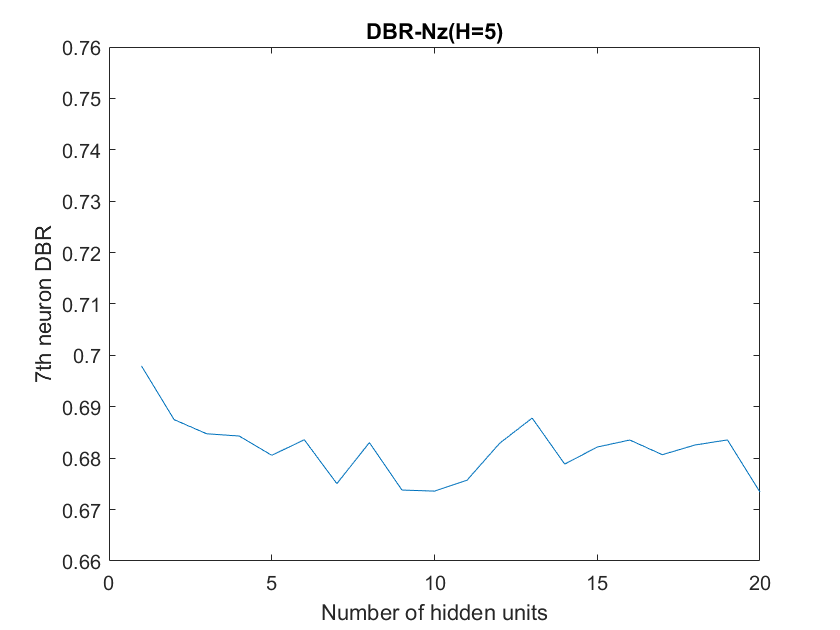

% ANN Nz-DBR
ANN_Nz_DBR = zeros(1,20);
Nzlist = 1:20;
for Nz=Nzlist
  bestDBR = Inf;
  for i=1:ceil(Nz/5)*16
    bestDBR = min(ANN_explore_Nz(Nz,i).DBR, bestDBR);
  end
  ANN_Nz_DBR(Nz)=bestDBR;
end
figure(1)
plot(Nzlist, ANN_Nz_DBR)
xlabel("Number of hidden units")
ylabel("7th neuron DBR")
ylim([0.66,0.76])
title(['DBR-Nz(H=', num2str(ANN_explore_Nz(1,1).H), ')'])

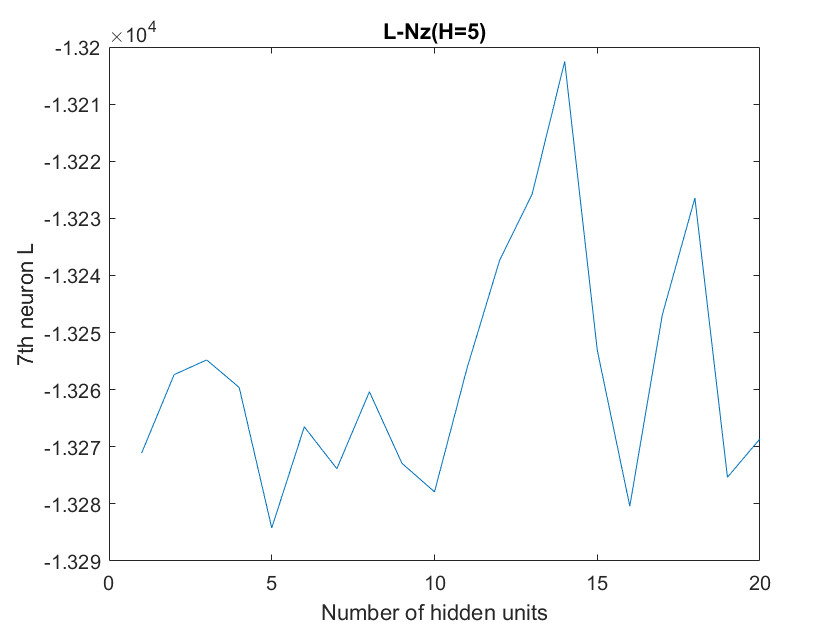

% ANN Nz-L
ANN_Nz_L = zeros(1,20);
Nzlist = 1:20;
for Nz=Nzlist
  bestL = -Inf;
  for i=1:ceil(Nz/5)*16
    bestL = max(ANN_explore_Nz(Nz,i).L, bestL);
  end
  ANN_Nz_L(Nz)=bestL;
end
figure
plot(Nzlist, ANN_Nz_L)
xlabel("Number of hidden units")
ylabel("7th neuron L")
title("L-Nz(H=5)")

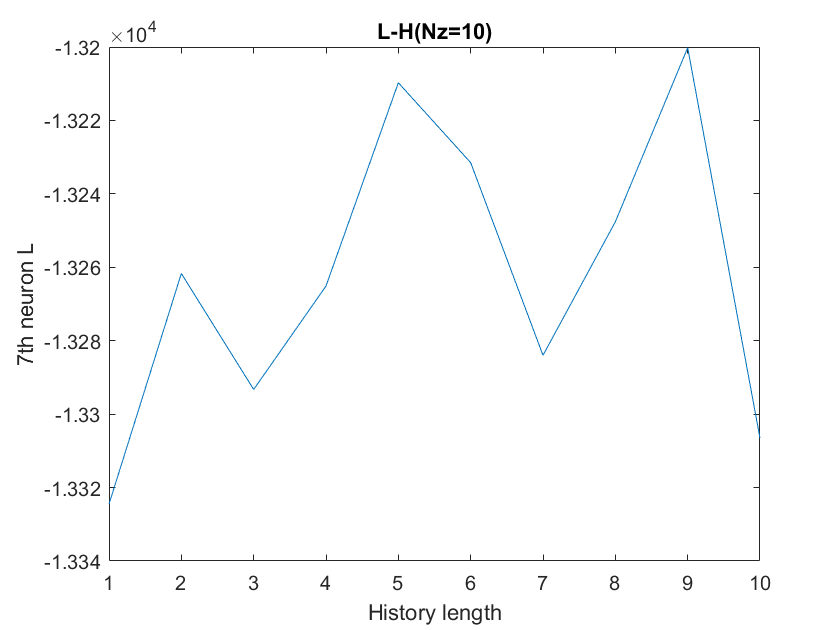

% ANN Nz-L
ANN_H_L = zeros(1,10);
for H=1:10
  bestL = -Inf;
  for i=1:30
    bestL = max(ANN_explore_H(H,i).L, bestL);
  end
  ANN_H_L(H)=bestL;
end
figure
plot(1:10, ANN_H_L)
xlabel("History length")
ylabel("7th neuron L")
title("L-H(Nz=10)")

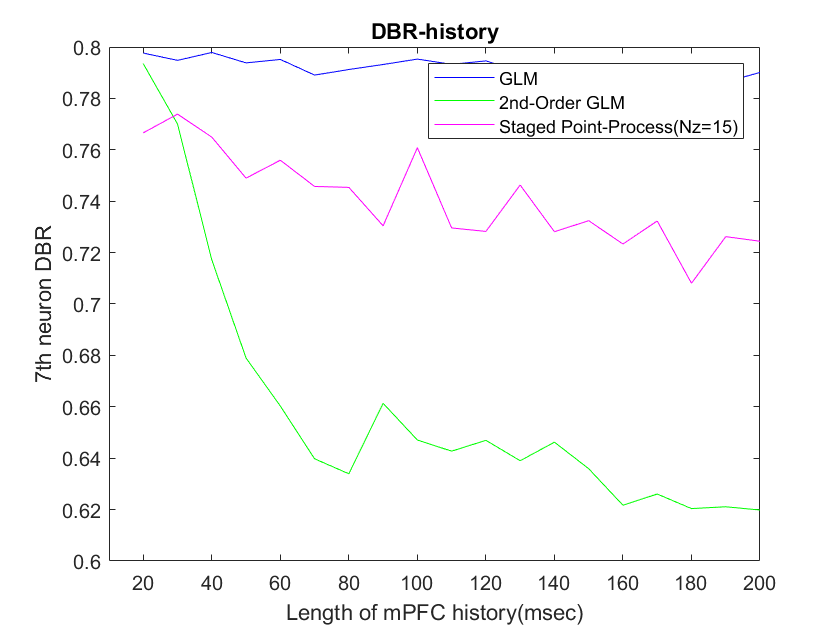

% get DBRs from differnt model result
GLM_sec_DBR = zeros(1,20);
GLM_DBR = zeros(1,20);
ANN_DBR = zeros(1,20);
% for i=1:16
%   GLM_sec_DBR(i) = GLM_sec_explore_H(i).DBR;
% end
for H=2:20
  GLM_DBR(H)     = GLM_explore_H(H).DBR;
  GLM_sec_DBR(H) = GLM_sec_explore_H(H).DBR;
  ANN_DBR_list = getFieldArray(ANN_explore_H, "DBR", H);
  ANN_DBR(H) = min(ANN_DBR_list);
end
% plot DBR-history result
figure(2)
plot(20:10:200, GLM_DBR(2:20), 'b')
hold on
plot(20:10:200, GLM_sec_DBR(2:20), 'g')
plot(20:10:200, ANN_DBR(2:20), 'm')
hold off
legend("GLM", "2nd-Order GLM", ['Staged Point-Process(Nz=', num2str(ANN_explore_H(1,1).Nz), ')'])
xlabel("Length of mPFC history(msec)")
xlim([10 200])
ylabel("7th neuron DBR")
title("DBR-history")

Take history = 100msec, kernel size = 0.3s

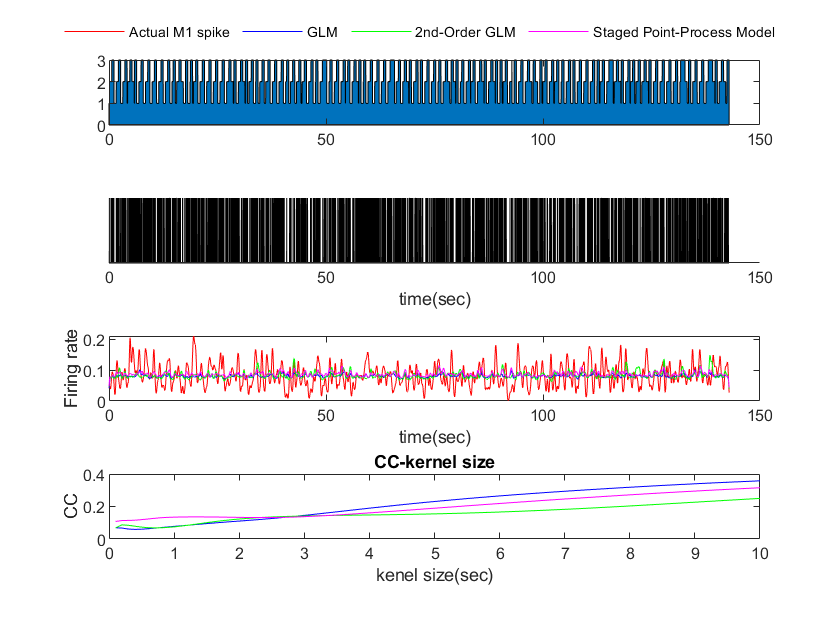

H=18;
% get GLM params & test result
W     = GLM_explore_H(H).W;
M1Idx = GLM_explore_H(H).M1Idx;
[~,~,~,trainX,~,testX,trainY,~,testY] = splitDataAdvance(1,mPFCspike,M1spike(:,M1Idx),eventTrain,optimalDelay(M1Idx),segTrain,H);
GLMtestLambdaYpre = GLMmodel(testX, W);
GLMtrainLambdaYpre = GLMmodel(trainX,W);
GLMccListTest = zeros(1, 1000/10);
GLMccListTrain = zeros(1, 1000/10);
% smooth result
for kernelSize=10:10:1000
  smoothedLambda    = gaussianSmooth(testY, kernelSize);
  smoothedLambdaPre = gaussianSmooth(GLMtestLambdaYpre, kernelSize);
  cc = corrcoef(smoothedLambda, smoothedLambdaPre);
  GLMccListTest(kernelSize/10) = cc(2);
  smoothedLambda    = gaussianSmooth(trainY, kernelSize);
  smoothedLambdaPre = gaussianSmooth(GLMtrainLambdaYpre, kernelSize);
  cc = corrcoef(smoothedLambda, smoothedLambdaPre);
  GLMccListTrain(kernelSize/10) = cc(2);
end
% 2nd Order GLM
W     = GLM_sec_explore_H(H).W;
M1Idx = GLM_sec_explore_H(H).M1Idx;
lagnum = GLM_sec_explore_H(H).lagnum;
lagalpha = GLM_sec_explore_H(H).lagalpha;
order = ['vm2-',num2str(lagnum),'-',num2str(lagalpha)];
[~,~,~,trainX,~,testX,trainY,~,testY,trainEvent,~,testEvent] = splitDataAdvance(order,mPFCspike,M1spike(:,M1Idx),eventTrain,optimalDelay(M1Idx),segTrain,H);
GLMsectestLambdaYpre = GLMmodel(testX, W);
GLMsectrainLambdaYpre = GLMmodel(trainX, W);
GLM_sec_ccListTest = zeros(1, 1000/10);
GLM_sec_ccListTrain = zeros(1, 1000/10);
% smooth
for kernelSize=10:10:1000
  smoothedLambda    = gaussianSmooth(testY, kernelSize);
  smoothedLambdaPre = gaussianSmooth(GLMsectestLambdaYpre, kernelSize);
  cc = corrcoef(smoothedLambda, smoothedLambdaPre);
  GLM_sec_ccListTest(kernelSize/10) = cc(2);
  smoothedLambda    = gaussianSmooth(trainY, kernelSize);
  smoothedLambdaPre = gaussianSmooth(GLMsectrainLambdaYpre, kernelSize);
  cc = corrcoef(smoothedLambda, smoothedLambdaPre);
  GLM_sec_ccListTrain(kernelSize/10) = cc(2);
end
% ANN
W     = ANN_explore_H(18,15).W;
M1Idx = ANN_explore_H(18,15).M1Idx;
Nz    = ANN_explore_H(18,15).Nz;
[~,~,~,trainX,~,testX,trainY,~,testY] = splitDataAdvance(1,mPFCspike,M1spike(:,M1Idx),eventTrain,optimalDelay(M1Idx),segTrain,H);
[~, Nx] = size(testX);
ANNtestLambdaYpre  = ANNmodel(testX,  W, Nx, Nz);
ANNtrainLambdaYpre = ANNmodel(trainX, W, Nx, Nz);
ANNccListTest = zeros(1, 1000/10);
ANNccListTrain = zeros(1, 1000/10);
% smooth
for kernelSize=10:10:1000
  smoothedLambda    = gaussianSmooth(testY, kernelSize);
  smoothedLambdaPre = gaussianSmooth(ANNtestLambdaYpre, kernelSize);
  cc = corrcoef(smoothedLambda, smoothedLambdaPre);
  ANNccListTest(kernelSize/10) = cc(2);
  smoothedLambda    = gaussianSmooth(trainY, kernelSize);
  smoothedLambdaPre = gaussianSmooth(ANNtrainLambdaYpre, kernelSize);
  cc = corrcoef(smoothedLambda, smoothedLambdaPre);
  ANNccListTrain(kernelSize/10) = cc(2);
end

% optimal smooth kernel size result
kernelSize = 100;
smoothedLambda = gaussianSmooth(trainY, kernelSize);
smoothedGLMLambdaPre = gaussianSmooth(GLMtrainLambdaYpre, kernelSize);
smoothedGLMsecLambdaPre = gaussianSmooth(GLMsectrainLambdaYpre, kernelSize);
smoothedANNLambdaPre = gaussianSmooth(ANNtrainLambdaYpre, kernelSize);

% display results
spikeLength = length(trainY);
index = 1:spikeLength;
t = index/100;
% t = 45:0.01:75;
% index = 4500:7500;
figure("Name", "Train")
subplot(4,1,1)
area((1:length(trainEvent))/100, trainEvent)
% area(t, trainEvent(index))
% real spike
subplot(4,1,2)
area(t, trainY(index))
xlabel("time(sec)")
set(gca, 'TickLength', [0 0])
set(gca, 'ytick', [])
set(gca, 'box', 'off')
% smoothed results
subplot(4,1,3)
h{1} = plot(t, smoothedLambda(index), 'r');
hold on
h{2} = plot(t, smoothedGLMLambdaPre(index), 'b');
h{3} = plot(t, smoothedGLMsecLambdaPre(index), 'g');
h{4} = plot(t, smoothedANNLambdaPre(index), 'm');
hold off
xlabel("time(sec)")
ylabel("Firing rate")
% cc analyze
subplot(4,1,4)
plot(0.1:0.1:10, GLMccListTrain, 'b')
hold on
plot(0.1:0.1:10, GLM_sec_ccListTrain, 'g')
plot(0.1:0.1:10, ANNccListTrain, 'm');
hold off
xlabel("kenel size(sec)")
xlim([0 10])
ylabel("CC")
title("CC-kernel size")
legend([h{1}; h{2}; h{3}; h{4}], "Actual M1 spike", "GLM", "2nd-Order GLM", ...
  "Staged Point-Process Model", "Position",[0.5  0.95  0  0], ...
  "Box","off", "Orientation","horizontal")

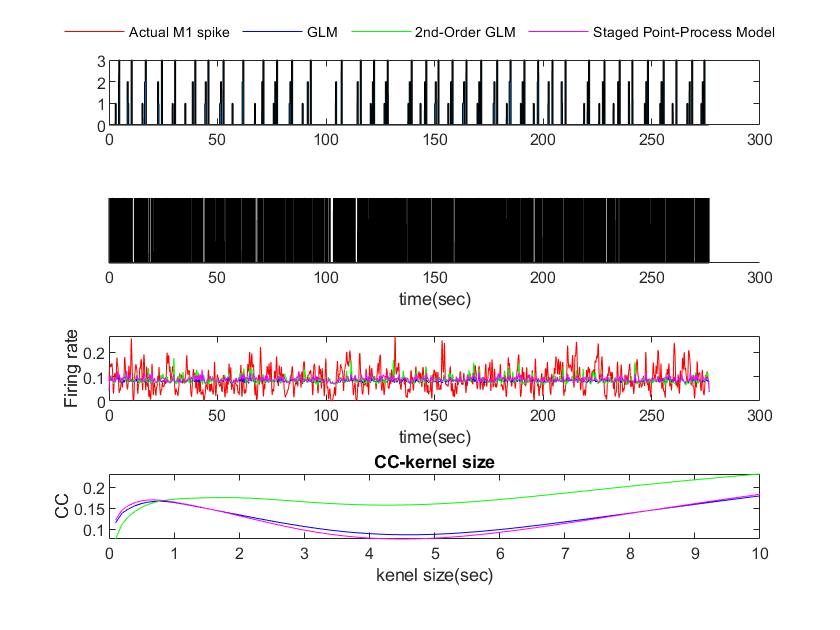

% optimal smooth kernel size result
kernelSize = 100;
smoothedLambda = gaussianSmooth(testY, kernelSize);
smoothedGLMLambdaPre = gaussianSmooth(GLMtestLambdaYpre, kernelSize);
smoothedGLMsecLambdaPre = gaussianSmooth(GLMsectestLambdaYpre, kernelSize);
smoothedANNLambdaPre = gaussianSmooth(ANNtestLambdaYpre, kernelSize);

% display results
spikeLength = length(testY);
index = 1:spikeLength;
t = index/100;
% t = 240:0.01:280;
% index = 24000:28000;
figure("Name", "Test")
subplot(4,1,1)
area((1:length(testEvent))/100, testEvent)
% area(t, testEvent(index))
% real spike
subplot(4,1,2)
area(t, testY(index))
xlabel("time(sec)")
set(gca, 'TickLength', [0 0])
set(gca, 'ytick', [])
set(gca, 'box', 'off')
% smoothed results
subplot(4,1,3)
h{1} = plot(t, smoothedLambda(index), 'r');
hold on
h{2} = plot(t, smoothedGLMLambdaPre(index), 'b');
h{3} = plot(t, smoothedGLMsecLambdaPre(index), 'g');
h{4} = plot(t, smoothedANNLambdaPre(index), 'm');
xlabel("time(sec)")
ylabel("Firing rate")
% cc analyze
subplot(4,1,4)
plot(0.1:0.1:10, GLMccListTest, 'b')
hold on
plot(0.1:0.1:10, GLM_sec_ccListTest, 'g')
plot(0.1:0.1:10, ANNccListTest, 'm');
hold off
xlabel("kenel size(sec)")
xlim([0 10])
ylabel("CC")
title("CC-kernel size")
legend([h{1}; h{2}; h{3}; h{4}], "Actual M1 spike", "GLM", "2nd-Order GLM", ...
  "Staged Point-Process Model", "Position",[0.5  0.95  0  0], ...
  "Box","off", "Orientation","horizontal")

% figure
% hold on
% for i=1:800
%   [Nz, idx] = getParamIndex(i);
%   LHistory = ANN_explore_Nz(Nz,idx).LHistory;
%   LHistory(LHistory==0) = nan;
%   h=plot(LHistory);
%   set(h, 'color', [i/800, i*i/640000, sqrt(i)/sqrt(800)])
% end
% hold off
% figure
% hold on
% for i=1:200
%   LHistory = ANN_explore_H(i).LHistory;
%   LHistory(LHistory==0) = nan;
%   h=plot(LHistory);
%   set(h, 'color', [i/200, i*i/40000, sqrt(i)/sqrt(200)])
% end
% hold off

% ANN
W     = ANN_explore_H(3,13).W;
M1Idx = ANN_explore_H(3,13).M1Idx;
Nz    = ANN_explore_H(3,13).Nz;
[~,~,~,trainX,~,testX,trainY,~,testY] = splitDataAdvance(1,mPFCspike,M1spike(:,M1Idx),eventTrain,optimalDelay(M1Idx),segTrain,H);
[~, Nx] = size(testX);
ANNtestLambdaYpre  = ANNmodel(testX,  W, Nx, Nz);

Index exceeds the number of array elements (171).

Error in ANNmodel (line 4)
w = reshape(W(1:Nx*Nz), Nx, Nz)';

% ANNtrainLambdaYpre = ANNmodel(trainX, W, Nx, Nz);

smoothedANNLambdaPre = gaussianSmooth(ANNtestLambdaYpre, kernelSize);
figure
plot(t, smoothedANNLambdaPre(index), 'g');

W     = ANN_explore_H(19,23).Whis(89,:);
M1Idx = ANN_explore_H(19,23).M1Idx;
Nz    = ANN_explore_H(19,23).Nz;
[~,~,~,trainX,~,testX,trainY,~,testY] = splitDataAdvance(1,mPFCspike,M1spike(:,M1Idx),eventTrain,optimalDelay(M1Idx),segTrain,19);
[~, Nx] = size(trainX);
ANNtestLambdaYpre  = ANNmodel(trainX,  W, Nx, Nz);
% ANNtrainLambdaYpre = ANNmodel(trainX, W, Nx, Nz);

smoothedANNLambdaPre = gaussianSmooth(ANNtestLambdaYpre, 50);
smoothedLambda = gaussianSmooth(trainY, 50);
t = 55:0.01:100;
index = 5500:10000;
figure
plot(t, smoothedANNLambdaPre(index), 'b');
hold on
plot(t, smoothedLambda(index), 'r');
hold off

for H=1:15
  [trainLen, valLen, testLen, trainX, valX, testX, trainY, valY, testY, trainEvent, valEvent, testEvent] = splitDataAdvance(2,mPFCspike,M1spike(:,1),eventTrain,optimalDelay(1),segTrain,H);
  save(['data\splitedData\secondOrder_', num2str(H), '.mat'], ...
      "trainLen", "valLen", "testLen", ...
      "trainX", "valX", "testX", ...
      "trainY", "valY", "testY", ...
      "trainEvent", "valEvent", "testEvent")
end